# ECE 537: Advanced Data Analytics

# Exercise #7: Correlation and Mutual Information

**Yilin Zhang, Jiaming Yang**

**1. Load the Exercise 7 Data Set, which consists of drawn data from two classes. For the first measurement feature vector apply an appropriate statistical goodness-of-fit test to determine whether or not the this feature is Gaussian.**

load("Exercise_7_data.mat")
feature_1 = data(:,1);
h = chi2gof(feature_1)

h = 1

According the Chi-square goodness-of-fit test, the first measurement feature is Gaussian.

**2. Determine the Bayes classification error rate for the data if the analysis is based solely on data taken from the first measurement feature. Note you can no longer simply assume that the data for each class is Gaussian distributed. Moreover, Bayes classification does not make this assumption but, instead applied generally to any class distribution.**

Fit Gaussian mixture model for the first measurement feature of class 0

P_0 = length(feature_1(class == 0)) / length(feature_1);
histogram(feature_1(class == 0))
hold on
AIC = zeros(1,4);
GMModels = cell(1,4);
options = statset('MaxIter',500);
for k = 1:4
    GMModels{k} = fitgmdist(feature_1(class == 0),k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= GMModels{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
numComponents

numComponents = 3

best_model_0 = GMModels{numComponents}

best_model_0 = 

在 1 个维中具有 3 个成分的高斯混合分布
成分 1:
混合比例: 0.506982
均值:    6.9671

成分 2:
混合比例: 0.369437
均值:    5.2346

成分 3:
混合比例: 0.123581
均值:    3.7911





Fit Gaussian mixture model for the first measurement feature of class 1

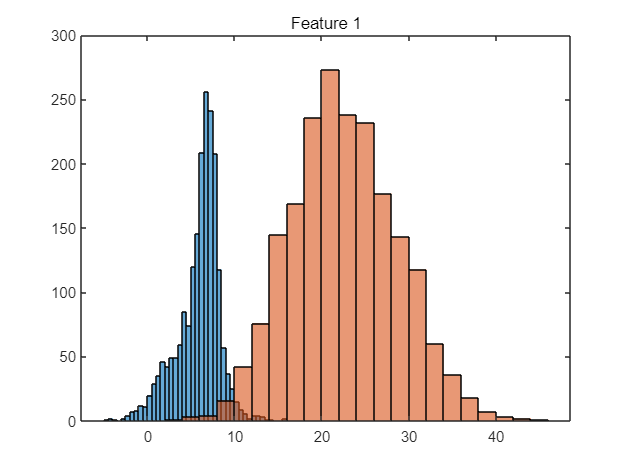

P_1 = length(feature_1(class == 1)) / length(feature_1);
histogram(feature_1(class == 1))
title("Feature 1")
hold off

AIC = zeros(1,4);
GMModels = cell(1,4);
options = statset('MaxIter',500);
for k = 1:4
    GMModels{k} = fitgmdist(feature_1(class == 1),k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= GMModels{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
numComponents

numComponents = 2

best_model_1 = GMModels{numComponents}

best_model_1 = 

在 1 个维中具有 2 个成分的高斯混合分布
成分 1:
混合比例: 0.805702
均值:   21.0050

成分 2:
混合比例: 0.194298
均值:   29.1194





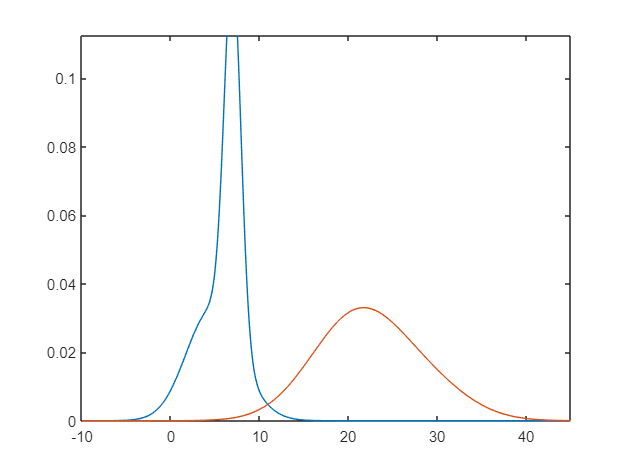

syms x
eqn = pdf_GMM(best_model_0, x) * P_0 == pdf_GMM(best_model_1, x) * P_1;
fplot([lhs(eqn) rhs(eqn)], [-10, 45])

x1 = vpasolve(eqn, x, -10)

$$x1 = -18.735547947510902265551560333852$$

x2 = vpasolve(eqn, x, 10)

$$x2 = 10.927428242617175204408042525772$$

x3 = vpasolve(eqn,x,50)

 
x3 =
 
Empty sym: 0-by-1
 


The decision regions of the two classes are


$$R_0 =\left(x_1 ,x_2 \right),\;R_1 =\left(-\infty ,x_1 \right)\cup \left(x_2 ,\infty \right)$$


The error rate is


$$P\left(\textrm{error}\right)=\int_{-\infty }^{x_1 } P\left(\omega_0 \right)p\left(x|\omega_0 \right)\textrm{dx}+\int_{x_1 }^{x_2 } P\left(\omega_1 \right)p\left(x|\omega_1 \right)\textrm{dx}+\int_{x_2 }^{\infty } P\left(\omega_0 \right)p\left(x|\omega_0 \right)\textrm{dx}$$


P_error_1 = int(lhs(eqn), x, [-inf x1]) + int(rhs(eqn), x, [x1 x2]) + int(lhs(eqn), x, [x2 inf])

$$P\_error\_1 = 0.017384771114337475470095902802585$$

**3. Determine the Bayes classification error rate for the data if the analysis is based solely on data taken from the second measurement feature.**

Fit Gaussian mixture model for the second measurement feature of class 0

feature_2 = data(:,2);
P_0 = length(feature_2(class == 0)) / length(feature_2);
histogram(feature_2(class == 0))
hold on
AIC = zeros(1,4);
GMModels = cell(1,4);
options = statset('MaxIter',500);
for k = 1:4
    GMModels{k} = fitgmdist(feature_2(class == 0),k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= GMModels{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
numComponents

numComponents = 1

best_model_0 = GMModels{numComponents}

best_model_0 = 

在 1 个维中具有 1 个成分的高斯混合分布
成分 1:
混合比例: 1.000000
均值:    9.9723





Fit Gaussian mixture model for the second measurement feature of class 1

P_1 = length(feature_2(class == 1)) / length(feature_2)

P_1 = 0.5000

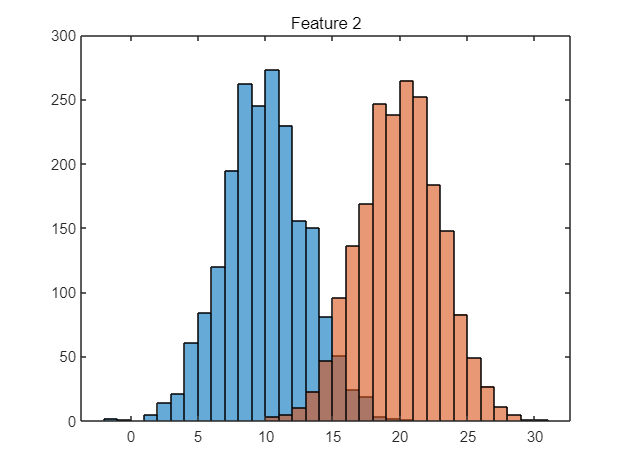

histogram(feature_2(class == 1))
title("Feature 2")
hold off

AIC = zeros(1,4);
GMModels = cell(1,4);
options = statset('MaxIter',500);
for k = 1:4
    GMModels{k} = fitgmdist(feature_2(class == 1),k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= GMModels{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
numComponents

numComponents = 1

best_model_1 = GMModels{numComponents}

best_model_1 = 

在 1 个维中具有 1 个成分的高斯混合分布
成分 1:
混合比例: 1.000000
均值:   20.0277





pdf(best_model_1, 10)

ans = 4.6753e-04

pdf_GMM(best_model_1, 10)

ans = 4.6753e-04

Compute the decision regions of the two classes

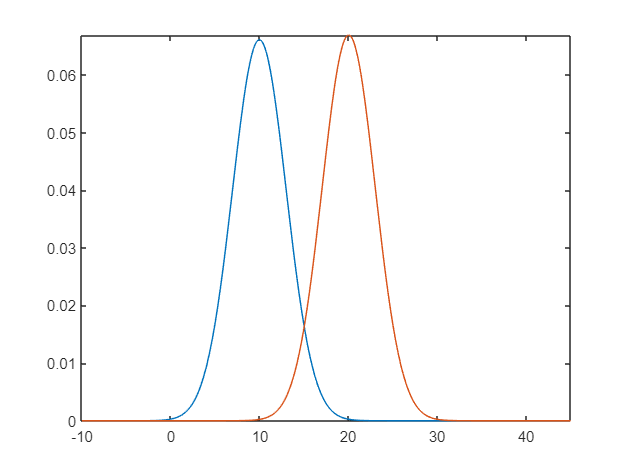

syms x
eqn = pdf_GMM(best_model_0, x) * P_0 == pdf_GMM(best_model_1, x) * P_1;
fplot([lhs(eqn) rhs(eqn)], [-10, 45])

x_s = vpasolve(eqn, x, 15)

$$x\_s = 15.019623897143392725032247002054$$

The decision regions of the two classes are


$$R_0 =\left(-\infty ,x^* \right),\;R_1 =\left(x^* ,\infty \right)$$


The error rate is


$$P\left(\textrm{error}\right)=\int_{-\infty }^{x^* } P\left(\omega_1 \right)p\left(x|\omega_1 \right)\textrm{dx}+\int_{x^* }^{\infty } P\left(\omega_0 \right)p\left(x|\omega_0 \right)\textrm{dx}$$


P_error_2 = int(rhs(eqn), x, [-inf x_s]) + int(lhs(eqn), x, [x_s inf])

$$P\_error\_2 = 0.046848728670250740172315925230628$$

**4. Determine the Bayes classification error rate for the data if the analysis is based on all of the available measurement features, where you will also need to apply proper data normalization.**

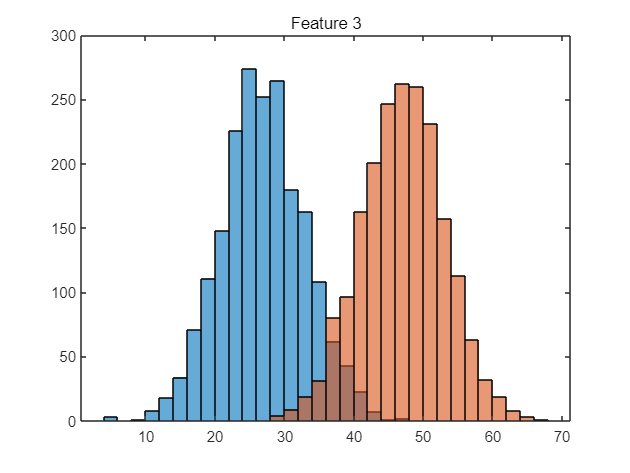

feature_3 = data(:,3);
histogram(feature_3(class == 0))
hold on
histogram(feature_3(class == 1))
title("Feature 3")
hold off

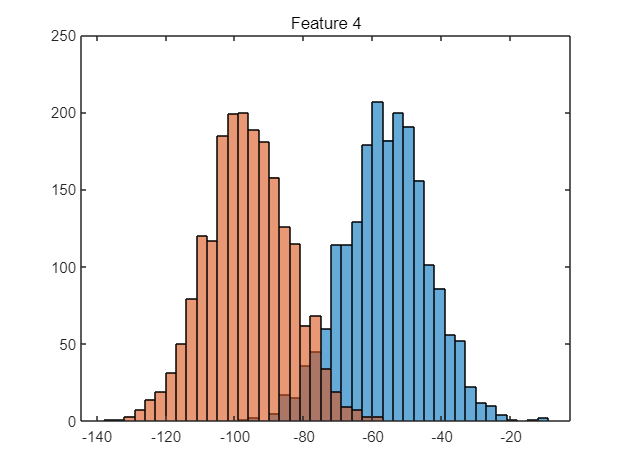

feature_4 = data(:,4);
histogram(feature_4(class == 0))
hold on
histogram(feature_4(class == 1))
title("Feature 4")
hold off

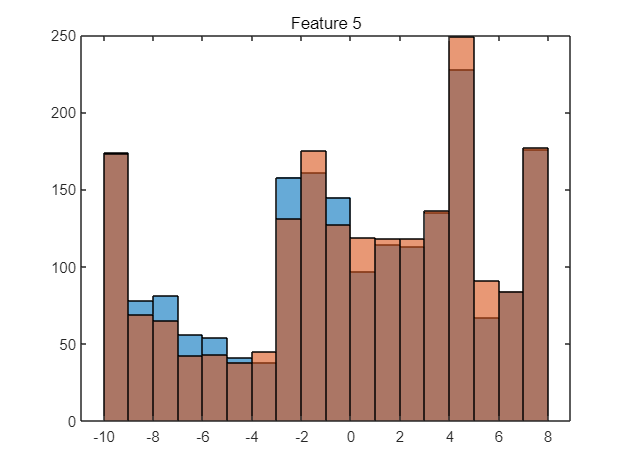

feature_5 = data(:,5);
histogram(feature_5(class == 0))
hold on
histogram(feature_5(class == 1))
title("Feature 5")
hold off

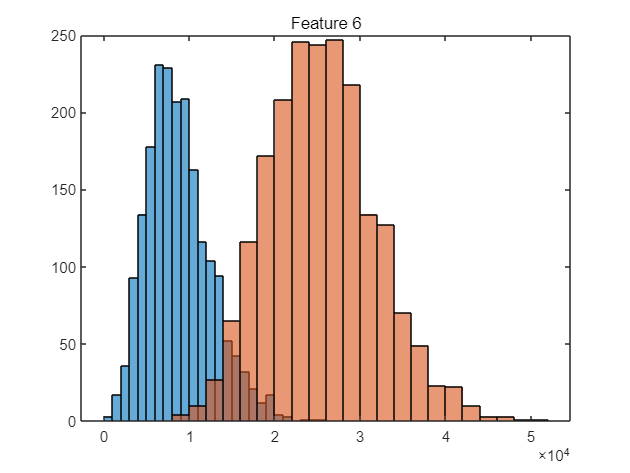

feature_6 = data(:,6);
histogram(feature_6(class == 0))
hold on
histogram(feature_6(class == 1))
title("Feature 6")
hold off

Normalize each feature to a range of [-1, 1]

neg_one_to_one_norm = @(feature, min, max) ((feature - min) ./ (max - min)) * 2 - 1;
data_norm = [neg_one_to_one_norm(feature_1, min(feature_1), max(feature_1)) neg_one_to_one_norm(feature_2, min(feature_2), max(feature_2)) neg_one_to_one_norm(feature_3, min(feature_3), max(feature_3)) neg_one_to_one_norm(feature_4, min(feature_4), max(feature_4)) neg_one_to_one_norm(feature_5, min(feature_5), max(feature_5)) neg_one_to_one_norm(feature_6, min(feature_6), max(feature_6))];

Fit Gaussian mixture model for the normalized data of class 0

AIC = zeros(1,4);
GMModels = cell(1,4);
options = statset('MaxIter',500);
for k = 1:4
    GMModels{k} = fitgmdist(data_norm(class == 0, :),k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= GMModels{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
numComponents

numComponents = 4

best_model_0 = GMModels{numComponents}

best_model_0 = 

在 6 个维中具有 4 个成分的高斯混合分布




Fit Gaussian mixture model for the normalized data of class 1

AIC = zeros(1,4);
GMModels = cell(1,4);
options = statset('MaxIter',1000);
for k = 1:4
    GMModels{k} = fitgmdist(data_norm(class == 1, :),k,'Options',options,'CovarianceType','diagonal');
    AIC(k)= GMModels{k}.AIC;
end

[minAIC,numComponents] = min(AIC);
numComponents

numComponents = 4

best_model_1 = GMModels{numComponents}

best_model_1 = 

在 6 个维中具有 4 个成分的高斯混合分布




Compute the decision regions of the two classes

% syms x
% eqn = pdf_GMM(best_model_0, x) * P_0 == pdf_GMM(best_model_1, x) * P_1;
fplot([lhs(eqn) rhs(eqn)], [-10, 45])

x_s = vpasolve(eqn, x)

 
x_s =
 
Empty sym: 0-by-1
 


**5. Determine the classification error for a neural network classifier trained on all of the available measurement features. Note, you will still need to properly partition the data into training and test sets.**

%Shuffle the data 7 times
for i = 1:7
    shuffle = randperm(size(data, 1));
    data = data(shuffle, :);
    class = class(shuffle);
end

%Randomly pick the training index
train_indx = randsample(size(data, 1), size(data, 1) * 0.25)';
train_set = data(train_indx, :);
target_train = class(train_indx);

%Use the remaining index as the test index
all_indx = 1:size(data, 1);
test_indx = setdiff(all_indx, train_indx);
test_set = data(test_indx, :);
target_test = class(test_indx);

%Pick validation set indeices from the training set indices
val_indx = randsample(train_indx, length(train_indx)*0.2);
train_indx_NN = setdiff(train_indx, val_indx);

%Template for setting up and training a pattern classification neural net
%which:
%uses predefined test/va/train sets according to indices
%
%-- A. Dimopoulos, June 2022

%all Data and labels. -->DEFINE THESE<--
Dall = data';
Tall = full(ind2vec(class+1));

%set indices. -->DEFINE THESE<--
%training indices
TRAIN_IND = train_indx_NN;
%validation indices
VAL_IND = val_indx;
%testing indices
TEST_IND = test_indx;

%declare a classification network with default number of hidden units
n = patternnet;
%assign train/val/test sets by index
n.divideFcn = 'divideind';
n.inputs{1}.processFcns

ans = 1×2 cell 数组
    {'removeconstantrows'}    {'mapminmax'}


n.divideParam.trainInd = TRAIN_IND;
n.divideParam.valInd = VAL_IND;
n.divideParam.testInd = TEST_IND;
%configure input and output sizes
n = configure(n,Dall,Tall);
%initialize the network weights
n = init(n);
%train the network
[n,train_record] = train(n,Dall,Tall,useGPU="yes");
% Test the Network
NN_pred_test_norm = n(Dall(:, TEST_IND));
yind = vec2ind(NN_pred_test_norm);
tind = vec2ind(Tall(:,TEST_IND));
error_NN_test_norm = sum(tind ~= yind)/numel(tind)

error_NN_test_norm = 0.0030

**6. Compute the statistical correlation between each of the measurement features. Are these features statistically independent?**

corr(data)

ans =     1.0000    0.7493    0.7493   -0.7493    0.0313    0.7423
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
    0.7493    1.0000    1.0000   -1.0000    0.0169    0.9893
   -0.7493   -1.0000   -1.0000    1.0000   -0.0169   -0.9893
    0.0313    0.0169    0.0169   -0.0169    1.0000    0.0178
    0.7423    0.9893    0.9893   -0.9893    0.0178    1.0000


These features are not statistically independent because the non-diagonal values of the correlation matrix are not 0.

**7. Discuss the differences and distinctions between the meanings of the terms statistical correlation and mutual information. Can features measurements assessed to be uncorrelated still share mutual information? **

**8. Discuss the impacts that including features with high correlation and/or mutual information will have on the performance of parametric and non-parametric classifiers. Is either classification approach less or more sensitive to the issues than the other?**

**9. Discuss methods available in the data analysis literature that could be used to help identify whether non-linear relationships may exist between feature measurements, where it should be noted that more complex relationship can exist which involve multiple feature vectors.**

function y = pdf_GMM(GMM, x)
    pdf_Gaussian = @(x, mu, sigma) (1/((norm(sigma)^(size(sigma, 1)/2))*sqrt(2*pi))) .* exp(dot(-(1/2)*mldivide(sigma,(x-mu)')', (x-mu), 2));
    y = 0;
    for i = 1:GMM.NumComponents
        y = y + GMM.ComponentProportion(i) .* pdf_Gaussian(x, GMM.mu(i), GMM.Sigma(:,:,i));
    end
end